
% Ignition is a matlab-based afterburner design program for use with hobby
% sized turbojet engines. The program works by getting user inputs about
% specific parameters realted to the engine and then back calculates initial
% turbine conditions. From there, the user will specify combustion
% parameters and the program will compute temperature and pressure post
% combustion. Using the above information, the program will design a
% prelimiary afterburner outputting a geometry file once the user is happy.
% Future iterations will include optimization and better UI along with
% easier to use and wider reaching combustion tools


clc;clear;close all;

%For the following, nozzle exit is treated as section '2' and turbine exit is
%treated as '1'

%Given / Known
d_turbine = 71e-3;
d_nozzle = 51e-3;
gamma = 1.4;
R = 287;

%Find Area at the nozzle (2) exit and turbine exit(1)
A1 = (pi*d_turbine^2)/4;
%A1 = pi32*(16e-3)^2;
A2 = (pi*d_nozzle^2)/4;

%Convert from C to K
T2 = 800;
T2 = T2 + 273.15;

%Convert from km/h to m/s
u2 = 1700;
u2 = u2*1000*(1/3600);

M2 = u2/sqrt(gamma*R*T2);

%Isentropic Area Relations
a2astar = aastar(M2,gamma);
Astar = A2/a2astar;

%Finds M1 using area relations. Outputs a vector but answer takes only
%real, subsonic answers (see M1 = M1(1))
syms M1
a1astar = aastar(M1,gamma);
M1 = vpasolve(A1/Astar == a1astar,M1);
M1 = M1(1);

%Find the stagnation temperature for the nozzle and then finds temp at
%section '1'
T2T0 = stagtemp(M2,gamma);

T0 = T2/T2T0;

T1T0 = stagtemp(M1,gamma);
T1 = T1T0*T0;

%calculate velocity coming out of the turbine => goes into the afterburner
%diffuser
u1 = M1*sqrt(gamma*R*T1);

%Need to make an initial assumption to complete the diffuser/ flame holder
%sections. We will take diameter of the afterburner to be 91mm. Will be set
%in relation to the turbine to make it easier to recalculate (less
%variables to reinput). Also need to pass in an ignition time parameter.
%Initial guess was collected from Table 2 in the AB report we're following.
%Will likely be adusted later.
%Diffuser Geometry
BVP = 0.9516;
rab = d_turbine/2 + 0.01;
Tc = 3.46e-4;
Vlmax = BVP*(rab/Tc)

Vlmax = 125.1382


Cp = (gamma*R)/(gamma-1);
T3 = T1 + (u1^2/(2*Cp)) - (Vlmax^2/(2*Cp));


M3 = Vlmax/(sqrt(gamma*R*T3));

%May not be needed. Realized I essentially redid the assumptions to back
%out a diameter of about the same value I assumed (came out to 88mm). 
% a1astar_diff = aastar(M1,gamma);
% Astar1 = A1/a1astar_diff;
% 
% a3astar_diff = aastar(M3,gamma);
% A3 = a3astar_diff*Astar1;
% 
% r3 = sqrt(A3/pi32);
% d3 = 2*r3*10^3;

%size of the turbine blades. Not sure exactly how to get this but roughly
%estimated using calipers and the good ole eye ball
turbblade = 16e-3;

% Define input parameters
r1_inner = turbblade;  % Inner inlet radius (meters)
r3_inner = 0; % Inner outlet radius (meters)

r1_outer = d_turbine/2;  % Outer inlet radius (meters)
r3_outer = rab; % Outer outlet radius (meters)
diff_length = 0.120;      % Diffuser length (meters)
n_points = 1000;    % Number of points along the length

% Generate x-coordinates (axial positions)
x = linspace(0, diff_length, n_points);

% Compute inner and outer radius values assuming linear increase
r_inner = linspace(r1_inner, r3_inner, n_points);
r_outer = linspace(r1_outer, r3_outer, n_points);

% Compute corresponding cross-sectional areas
A_inner = pi * r_inner.^2; % Inner area (hollow region)
A_outer = pi * r_outer.^2; % Outer total area
A_flow = A_outer - A_inner; % Flow area (actual open space)
straight = 0.1;

% Combine into a matrix for CSV output
data = [x' r_inner' r_outer' A_inner' A_outer' A_flow'];

% %creates and saves a CSV file. Will be implemented later to save the geometry of the 
% afterburner. Everything including flame holder, diffuser, etc will be included in the  
% csv file.
% Will likely need to crank up the number of points used for
% %a good geometry. 
%csv_filename = 'diffuser_geometry.csv';
%csvwrite(csv_filename, data);
%fprintf('CSV file "%s" created successfully.\n', csv_filename);

%Flame holder Geometry
theta = 15; %industry standard
D = 0.25;
D = D*0.0254;%Converts from in to m
r_diff = D/2;
l_diff =0.025; %r_diff/tand(theta); %may need to alter later. Flame holder just seems way too small in the plot atm


%Combustion Calculation

%Given
mdot_in = 300; %in L/s
mdot_in = mdot_in*10^-3; %m^3/s
mdot_fuel = 540; %g/min
mdot_fuel = mdot_fuel*(1/1000)*(1/60); %kg/s
rho_air = 1.225; %density of air at sea level. Will need to be more accurate for optimization

%Find the mass flow rate of the incoming air only
mdot_total = rho_air*mdot_in;
mdot_air = mdot_total - mdot_fuel

mdot_air = 0.3585


f_act = mdot_fuel/mdot_air;


P3 = 2.179;%atm %Pressure needs to be in bar to pass into the combustion toolbox
P3 = P3*1.01325;
%P3 = Units.convert(2.179,'atm','bar');


%Combustion Toolbox stuff

% Number passing into the toolbox needs to be an actual value. 
% Comes out as a weird symbolic thing from earlier calculations
T3 = eval(T3)

T3 = 1.1764e+03


MW_carbon = 12.011;
MW_oxygen = 15.999;
MW_nitrogen = 14.007;
MW_hydrogen = 1.0078;
MW_fuel = 12*MW_carbon + 24*MW_hydrogen;
MW_oxidizer = 2*MW_oxygen + 3.74*2*MW_nitrogen; %Not sure if this is correct (ie supposed to not include the nitrogen)
f_st = MW_fuel/(18*MW_oxidizer)

f_st = 0.0684


phi = f_act/f_st

phi = 0.3672


mol_air_new = 18/phi;



% Import packages
import combustiontoolbox.databases.NasaDatabase
import combustiontoolbox.core.*
import combustiontoolbox.equilibrium.*
import combustiontoolbox.common.Units

DB = NasaDatabase();

NASA database with thermo loaded from the main path ... OK!



system = ChemicalSystem(DB);
mix = Mixture(system);

set(mix,{'Jet_AbLb'},'fuel', 1);
set(mix,{'O2','N2'},'oxidizer',[18,67.32]/18); %needs to normalize around 1 mol of O2 (Alberto said this)
mixArray1 = setProperties(mix,'temperature',T3,'pressure',P3,'equivalenceRatio',1); % 1=> stoiciometric combustion

mixArray2 = mixArray1.copy(); %For the products

solver = EquilibriumSolver('problemType','HP'); %adiabatic and constant P

combustion = solver.solveArray(mixArray2);

************************************************************************************************************
------------------------------------------------------------------------------------------------------------
Problem type: HP  | Equivalence ratio = 1.0000
------------------------------------------------------------------------------------------------------------
               |    MIXTURE 1
T [K]          |      2691.9692
p [bar]        |         2.2079
r [kg/m3]      |         0.2756
h [kJ/kg]      |       953.1033
e [kJ/kg]      |       151.9902
g [kJ/kg]      |    -25290.0995
s [kJ/(kg-K)]  |         9.7487
W [g/mol]      |        27.9390
(dlV/dlp)T [-] |        -1.0101
(dlV/dlT)p [-] |         1.2456
cp [kJ/(kg-K)] |         3.2976
gamma [-]      |         1.1609
gamma_s [-]    |         1.1494
sound vel [m/s]|       959.5691
------------------------------------------------------------------------------------------------------------
MIXTURE 1               Xi [-]
N2      


Tpost = combustion.T;
Ppost = combustion.p;
fprintf('Temperature = %f K',Tpost);

Temperature = 2691.969152 K

Ppost = Units.convert(Ppost, 'bar','Pa');
Ppost = Ppost*10^-3;
fprintf('Pressure = %f kPa',Ppost);

Pressure = 220.787175 kPa




%Nozzle Stuff
Mpost = Vlmax/(sqrt(gamma*R*Tpost))

Mpost = 0.1203

A_comb_chamber = pi*(0.0455^2)

A_comb_chamber = 0.0065

%For converging nozzle, assume Mexit = 1
Mexit = 1;
Aexit = ((Mpost*A_comb_chamber)/Mexit)*sqrt(((1+((gamma-1)/2)*Mexit^2)/(1+((gamma-1)/2)*Mpost^2))^((gamma+1)/(gamma-1)))

Aexit = 0.0013

rexit = sqrt(Aexit/pi)

rexit = 0.0207

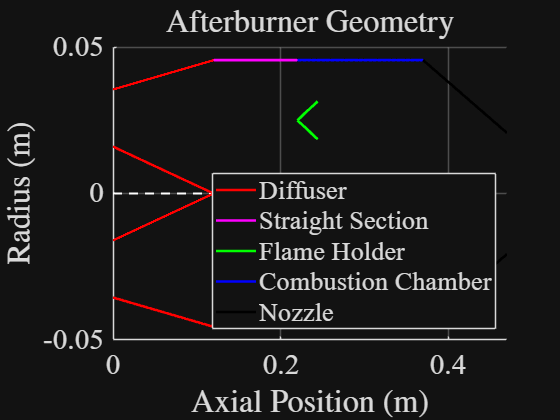




% Plot geometry

%plot color can be fully implemented later
%plotcolor = [0.12,0.01,0.01];
plotcolord = 'r';
plotcolore = 'm';
plotcolorf = 'g';

figure;
hold on;

%Plots the diffuser
plot([min(x),0.3], [0,0], 'w--', 'LineWidth', 1.5); % Horizontal x-axis as white dashed line
plot(x, r_outer, 'Color', plotcolord, 'LineWidth', 2);
plot(x, -r_outer, 'Color',plotcolord, 'LineWidth', 2); 
plot(x, r_inner, 'Color',plotcolord, 'LineWidth', 2); 
plot(x, -r_inner, 'Color',plotcolord, 'LineWidth', 2); 

%Plots straight expanding section
plot([diff_length, diff_length + straight], [r3_outer, r3_outer], 'Color', plotcolore, 'LineWidth', 2);
plot([diff_length, diff_length + straight], [-r3_outer, -r3_outer], 'Color', plotcolore, 'LineWidth', 2);

%Plots the flame holder
flame_holder_start = [0.22, 0.025]; 

x_v1 = flame_holder_start(1) + l_diff * cosd(theta);
y_v1 = flame_holder_start(2) + l_diff * sind(theta);
x_v2 = flame_holder_start(1) + l_diff * cosd(theta);
y_v2 = flame_holder_start(2) - l_diff * sind(theta);

plot([flame_holder_start(1), x_v1], [flame_holder_start(2), y_v1], 'Color', plotcolorf, 'LineWidth', 2);
plot([flame_holder_start(1), x_v2], [flame_holder_start(2), y_v2], 'Color', plotcolorf, 'LineWidth', 2);
plot([flame_holder_start(1), x_v1], [-flame_holder_start(2), -y_v1], 'Color', plotcolorf, 'LineWidth', 2);
plot([flame_holder_start(1), x_v2], [-flame_holder_start(2), -y_v2], 'Color', plotcolorf, 'LineWidth', 2);

%Combustion Chamber
x_combustion = linspace(0.22, 0.22 + (straight * 1.5), 100); % Define x range
y_combustion = ones(size(x_combustion)) * 0.0455; % Constant y-value

plot(x_combustion, y_combustion, 'b','LineWidth',2); % Plot the combustion chamber section
plot(x_combustion, -y_combustion, 'b','LineWidth',2); % Plot the combustion chamber section

%Nozzle
x_start = 0.37; % Define starting x position

x_nozzle = linspace(x_start, x_start + 0.1, 50); % Nozzle length
y_nozzle = linspace(0.0455, rexit, 50);  % Linear taper from initial to final radius
plot(x_nozzle, -y_nozzle, 'k', 'LineWidth', 2);
plot(x_nozzle, y_nozzle, 'k', 'LineWidth', 2);

grid on;
xlabel('Axial Position (m)');
ylabel('Radius (m)');
title('Afterburner Geometry');

%legend
leg_diff = plot(NaN,NaN,'Color',plotcolord,'LineWidth',2);
leg_str = plot(NaN,NaN,'Color',plotcolore,'LineWidth',2);
leg_fl = plot(NaN,NaN,'Color',plotcolorf,'LineWidth',2);
leg_comb = plot(NaN,NaN,'Color','b','LineWidth',2);
leg_noz = plot(NaN,NaN,'Color','k','LineWidth',2);
legend([leg_diff,leg_str,leg_fl,leg_comb,leg_noz],'Diffuser','Straight Section','Flame Holder','Combustion Chamber','Nozzle','location','southeast');
hold off;


disp(r_outer(end));

    0.0455





function aas = aastar(M,gamma)
    aas = (1/M)*(2/(gamma+1)*(1+((gamma-1)/2)*M^2))^((gamma+1)/(2*(gamma-1)));
end

function TT0 = stagtemp(M,gamma)
    TT0 = (1+((gamma-1)/2)*M^2)^-1;
end